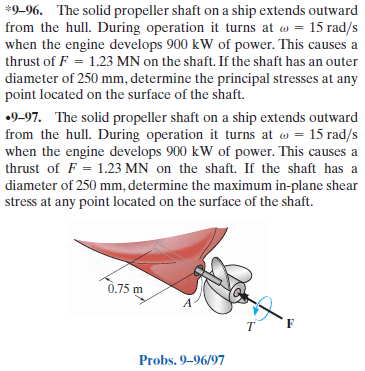

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-9-problem-96RP-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-9-problem-96RP-solution-9780136022305) (problem 9-96)

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-9-problem-97RP-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-9-problem-97RP-solution-9780136022305) (problem 9-97)

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# section properties

D = 250*u.mm;
C = D/2;
A = sympi*C^2;
J = sympi*C^4/2;

# loads at point A

Tdot = 900*u.kW;
omega = 15*u.rad/u.s;
T = rewrite(Tdot/omega*u.rad, [u.kN u.m])

$$T = 60\,\mathrm{kN}\,m$$

F = -1.23*u.MN;

# stresses at point A

% --------------
% - axial stress
% --------------
sigma_axial = rewrite(F/A, u.MPa);
sigma_axial_vpa = vpa(sigma_axial, 4) %#ok<NASGU> 

$$sigma\_axial\_vpa = -25.06\,\mathrm{MPa}$$

% ------------------
% - torsional stress
% ------------------
tau_torsion = rewrite(T*C/J, u.MPa);
tau_torsion_vpa = vpa(tau_torsion, 4) %#ok<NASGU> 

$$tau\_torsion\_vpa = 19.56\,\mathrm{MPa}$$

# mohr stresses at point A

sigmax = sigma_axial;
sigmax_vpa = vpa(sigmax, 4) %#ok<NASGU> 

$$sigmax\_vpa = -25.06\,\mathrm{MPa}$$

sigmay = sym(0)

$$sigmay = 0$$

tauxy = tau_torsion;
tauxy_vpa = vpa(tauxy, 4) %#ok<NASGU> 

$$tauxy\_vpa = 19.56\,\mathrm{MPa}$$

[sigmaxp sigmayp tauxyp thetap] = beam.principal(sigmax, sigmay, tauxy);
[sigmaxs sigmays tauxys thetas] = beam.max_shear(sigmax, sigmay, tauxy);

# mohr's circle for point A

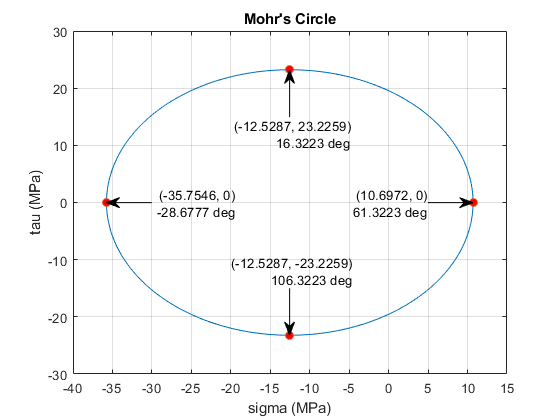

beam.mohr_plot(sigmax, sigmay, tauxy, {'MPa'});
axis([-40 15 -30 30])
xvals = double(separateUnits([sigmaxp sigmaxs]));
yvals = double(separateUnits([tauxyp tauxys]));
thetavals = double(separateUnits([thetap thetas]));
hold on;
plot(xvals, yvals, 'o', 'MarkerFaceColor', 'r');
for k = 1:4
  switch k
    case 1
      x1 = -30;
      y1 = 0;
    case 2
      x1 = 5;
      y1 = 0;
    case 3
      x1 = xvals(3);
      y1 = 15;
    case 4
      x1 = xvals(4);
      y1 = -15;
  end
  [x1 y1] = ds2nfu(x1, y1);
  [x2 y2] = ds2nfu(xvals(k), yvals(k));
  text_str = {['(' num2str(xvals(k)) ', ' num2str(yvals(k)) ')']
              [num2str(thetavals(k)) ' deg']};
  annotation('textarrow', [x1 x2], [y1 y2], 'String', text_str);
end

# clean up

assume(old_assum);
clear old_assum;
clear sigma_axial_vpa tau_torsion_vpa;
clear sigmax_vpa tauxy_vpa;
clear xvals yvals thetavals k x1 y1 x2 y2 text_str;